clc; clear all; close all;

img_path = fullfile('OD_sinCaps_1205_SQ_9_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('metadata', 'Correct.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);
load('meanHistRGB9_dobles.mat');%esto te da la variable MeanHistRGB

brightest_region_86_image_path = fullfile('Brightest_Region_G','Brightest_region_86_opcionDobles_Y_segundoUmbral');
brightest_region_86_image_path_0_objects = fullfile('Brightest_Region_G','Brightest_region_86_opcionDobles_Y_segundoUmbral','0_objects');
brightest_region_86_image_path_big_objects = fullfile('Brightest_Region_G','Brightest_region_86_opcionDobles_Y_segundoUmbral','big_objects');
OD_zoom_brightest_region_86_image_path = fullfile('Brightest_Region_G','Brightest_region_86_opcionDobles_Y_segundoUmbral','z');

tR=0.5;
tG=2;
tB=1;

margen_zoom=190;
margen_zoomed=500;

%for u = 1:height(T)
    k=2

k = 2


% Leer la imagen original y ponerla en las dimensiones que hemos
% establecido para que sea siempre igual
RGB = imread(string(fullfile(img_path, T{k,1})));
[alto_original, ancho_original, ~] = size(RGB);
RGB = imresize(RGB, [NaN, 3000], 'bicubic'); %Quiero que tenga ancho de 3000 y la altura me da igual, se ajusta automáticamente, lo he hecho así xke no todas las iamgenes tienen el mismo encuadre

% Quito los artefactos que hay a veces
RGB_g=rgb2gray(RGB);
loNOnegro=RGB_g>10;
loNOnegro=imerode(loNOnegro, strel('disk',30));
loNOnegro=imdilate(loNOnegro, strel('disk',30));
RGB=double(RGB);
RGB=RGB.*loNOnegro;
RGB=uint8(RGB);

% Le paso un filtro para quitarle el ruido
RGB(:,:,1)=medfilt2(RGB(:,:,1),[3 3],"symmetric");
RGB(:,:,2)=medfilt2(RGB(:,:,2),[3 3],"symmetric");
RGB(:,:,3)=medfilt2(RGB(:,:,3),[3 3],"symmetric");

% Cojo the brightest region en el G channel

    R = RGB(:,:,1); % Escoger el canal rojo de la imagen.
    
    Tr = graythresh(R);
    IrT = imbinarize(R, Tr);
    IrTE = edge(IrT, 'Sobel');
    IrTE = imdilate(IrTE,strel('disk',30));

    G=RGB(:,:,2);
    BrightestReg = G>0.86*max(G(:));
    BrightestReg = imclose(BrightestReg, strel('disk', 100));
    BrightestReg = imerode(BrightestReg, strel('disk', 10));

    cc1 = bwconncomp(BrightestReg);
    
    % Label connected components touching the mask IrTE
    IgT_touched = false(size(BrightestReg));
    for j = 1:cc1.NumObjects
        % Check if any pixel in the connected component touches the mask
        if any(IrTE(cc1.PixelIdxList{j}))
            IgT_touched(cc1.PixelIdxList{j}) = true; % Mark as touched
        end
    end
   
    % Remove connected components that touch the mask
    IgT_cleaned = BrightestReg - IgT_touched;

    cc2 = bwconncomp(IgT_cleaned);
    correlacion=zeros(1,cc2.NumObjects);
     
    % En el caso de que se encuentres dos objetos, se hace tempalte
    % matching para ver cual pertenece al OD
    if cc2.NumObjects>1

        L = bwlabel(IgT_cleaned,4);%se enumeran los objetos

        for i=1:cc2.NumObjects
            objektua=L==i;
            stats = regionprops(objektua,"Centroid","MajorAxisLength");

            if stats.MajorAxisLength>1000
                correlacion(i)=0;
            else
                centroideX=floor(stats.Centroid(1));
                centroideY=floor(stats.Centroid(2));

                margen_zoom=250;
    
                if centroideY+margen_zoom>height(objektua)
                   centroideY=height(objektua)-margen_zoom;
                elseif centroideY-margen_zoom<1
                    centroideY=margen_zoom+1;
                end
                
                if centroideX+margen_zoom>width(objektua)
                   centroideX=width(objektua)-margen_zoom;
                elseif centroideX-margen_zoom<1
                    centroideX=margen_zoom+1;
                end

                margen_zoom=190;
                dif=zeros(1,3);
                for s=1:3
                    layer_zoom=RGB(centroideY-margen_zoom:centroideY+margen_zoom, centroideX-margen_zoom:centroideX+margen_zoom, s);
                    [hist_layer, ~] = imhist(layer_zoom);
                    dif(s)=sum(bsxfun(@minus, hist_layer, meanHistRGB(:,s)).^2);
                end
                c=1./(1+dif);
                correlacion(i) = c(1).*tR + c(2).*tG + c(3);

            end          
        end
        [~, indx_max] = max(correlacion);
        IgT_cleaned=L==indx_max;
    end

% Ahora voy a poner un codigo para que las imagenes que tienen 0 objetos
% vuelvan a someterse al mismo código pero con un threshold menor
    if cc2.NumObjects==0
        BrightestReg = G>0.6*max(G(:));
        BrightestReg = imclose(BrightestReg, strel('disk', 100));
        BrightestReg = imerode(BrightestReg, strel('disk', 10));
    
        cc1 = bwconncomp(BrightestReg);
        
        % Label connected components touching the mask IrTE
        IgT_touched = false(size(BrightestReg));
        for j = 1:cc1.NumObjects
            % Check if any pixel in the connected component touches the mask
            if any(IrTE(cc1.PixelIdxList{j}))
                IgT_touched(cc1.PixelIdxList{j}) = true; % Mark as touched
            end
        end
       
        % Remove connected components that touch the mask
        IgT_cleaned = BrightestReg - IgT_touched;
    
        cc2 = bwconncomp(IgT_cleaned);
        correlacion=zeros(1,cc2.NumObjects);
         
        % En el caso de que se encuentres dos objetos, se hace tempalte
        % matching para ver cual pertenece al OD
        if cc2.NumObjects>1
    
            L = bwlabel(IgT_cleaned,4);%se enumeran los objetos
    
            for i=1:cc2.NumObjects
                objektua=L==i;
                stats = regionprops(objektua,"Centroid","MajorAxisLength");
    
                if stats.MajorAxisLength>1000
                    correlacion(i)=0;
                else
                    centroideX=floor(stats.Centroid(1));
                    centroideY=floor(stats.Centroid(2));
    
                    margen_zoom=250;
        
                    if centroideY+margen_zoom>height(objektua)
                       centroideY=height(objektua)-margen_zoom;
                    elseif centroideY-margen_zoom<1
                        centroideY=margen_zoom+1;
                    end
                    
                    if centroideX+margen_zoom>width(objektua)
                       centroideX=width(objektua)-margen_zoom;
                    elseif centroideX-margen_zoom<1
                        centroideX=margen_zoom+1;
                    end
    
                    margen_zoom=190;
                    dif=zeros(1,3);
                    for s=1:3
                        layer_zoom=RGB(centroideY-margen_zoom:centroideY+margen_zoom, centroideX-margen_zoom:centroideX+margen_zoom, s);
                        [hist_layer, ~] = imhist(layer_zoom);
                        dif(s)=sum(bsxfun(@minus, hist_layer, meanHistRGB(:,s)).^2);
                    end
                    c=1./(1+dif);
                    correlacion(i) = c(1).*tR + c(2).*tG + c(3);
    
                end          
            end
            [~, indx_max] = max(correlacion);
            IgT_cleaned=L==indx_max;
        end
    end

I=rgb2gray(RGB);
brightest_region = imoverlay(I,IgT_cleaned,'blue');



% if cc2.NumObjects==0
%     nombre_archivo2 = cell2mat(fullfile(brightest_region_86_image_path_0_objects, T{k,1})); 
%   %  imwrite(brightest_region, nombre_archivo2);
% else
%     stats = regionprops(IgT_cleaned,"MajorAxisLength");
%     if stats.MajorAxisLength>400
%     nombre_archivo3 = cell2mat(fullfile(brightest_region_86_image_path_big_objects, T{k,1})); 
%     %imwrite(brightest_region, nombre_archivo3);
%     end
% end

nombre_archivo = cell2mat(fullfile(brightest_region_86_image_path, T{k,1})); 
%imwrite(brightest_region, nombre_archivo);

cc3 = bwconncomp(IgT_cleaned);

    if cc3.NumObjects==1
        stats = regionprops(IgT_cleaned,"Centroid");
        centroideY=round(stats.Centroid(2));
        centroideX=round(stats.Centroid(1));
    
        if centroideY+margen_zoomed>height(RGB)
           centroideY=height(RGB)-margen_zoomed;
        elseif centroideY-margen_zoomed<1
            centroideY=margen_zoomed+1;
        end
                            
        if centroideX+margen_zoomed>width(RGB)
           centroideX=width(RGB)-margen_zoomed;
        elseif centroideX-margen_zoomed<1
            centroideX=margen_zoomed+1;
        end
        
        OD_zoom=RGB(centroideY-margen_zoomed:centroideY+margen_zoomed,centroideX-margen_zoomed:centroideX+margen_zoomed,:);
        OD_zoom=uint8(OD_zoom);
    
    else
            OD_zoom=uint8(zeros(1001,1001,3));
    end



%nombre_archivo = cell2mat(fullfile(OD_zoom_brightest_region_86_image_path, T{k,1})); 
%imwrite(OD_zoom, nombre_archivo);

iteration process

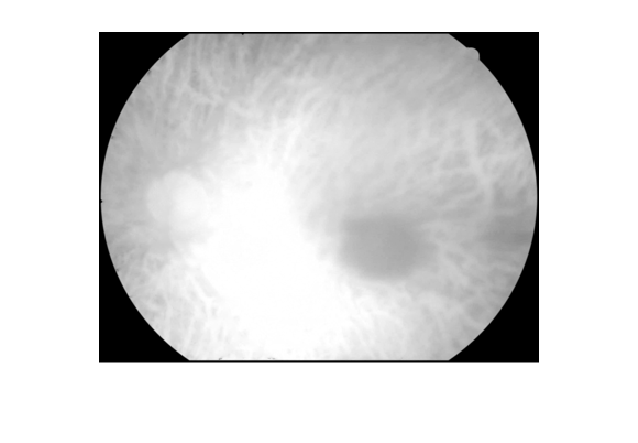

I=RGB(:,:,1);

if ndims(I)==3
    I1=rgb2gray(I);
else
    I1=I;
end


I1=imresize(I1, [300,400]);
m=zeros(size(I));
margen_zoomed=margen_zoomed.*0.5;
m(centroideY-margen_zoomed:centroideY+margen_zoomed,centroideX-margen_zoomed:centroideX+margen_zoomed)=1;
m=imresize(m, [300,400]);
figure, imshow(I1);

title ('Input Image');
I2=imresize(I1, 0.5);
m=imresize(m, 0.5);

figure;
subplot(2,2,1); imshow(I2); title('Input Image');
subplot(2,2,2); imshow(m); title('Initialization');
subplot(2,2,3); title('Segmentation');

seg = region_seg(I2, m, 50); %-- Run segmentation

subplot(2,2,4); imshow(seg); title('Global Region-Based Segmentation');

seg=imresize(seg, [size(I1,1), size(I1,2)]);
figure, imshow(seg);
title('Contour Image');

for i=1:300
    for j=1:400
        if seg(i,j)==0
            I1(i,j)=0;
        end
    end
end
 
figure,imshow (I1);

stats=regionprops (im2bw (I1), 'Area', 'BoundingBox');
a=[stats.Area]==max([stats.Area]);
box1=round(stats(a).BoundingBox);
hold on
rectangle('Position', box1, 'EdgeColor', 'g', 'LineWidth', 3), title('Image With Extracted Pixels');
img=imcrop(I1,box1);
figure
imshow(img);

title ('Input Image');
img=imresize(img, [300,400]);
%m=zeros(size(I1,1), size(I1,2));
%m(90:222,110:325) = 1;
img2=imresize(img,0.5);
%m=imresize(m, 0.5);

figure,
subplot(2,2,1); imshow(img); title('Input Image');
subplot(2,2,2); imshow(m); title('Initialization');
subplot(2,2,3); title('Segmentation');

seg1 = region_seg(img2, m, 300); %-- Run segmentation

subplot(2,2,4); imshow(seg1); title('Global Region-Based Segmentation');

figure,
BW = roipoly(seg1);

BW=edge(BW,'canny');
imshow(BW);
[y, x] = find(BW);
%x1=max(x);
%y1=max(y);
figure
a=area(x,y);
%lengthOfEdges = sum(BW);
a=a/1000;

if a<20
    disp('Glaucoma is detected');
else
    disp('No Glaucoma Detected');
end

%end